# Prediction of Couscous Moisture Diffusivity and Dryer Operating Conditions

Kathryn Atherton

ABE 557

October 25, 2018

clear
clc

## Part 1 Problem:

Develop a working algorithm (detailed calculation process) using Math Lab to determine the diffusivity of moisture of a couscous product as a function of temperature, moisture, and porosity based on equilibrium moisture. 

GAB  model coefficients for couscous flour at various temperatures:

Temp = [20, 35, 50, 60]+273.15;
Mo = [11.8, 6.45, 5.92, 3.53];
K = [0.65, 0.71, 0.72, 0.76];
C = [4.21, 8.77, 10.01];

## Part A: Determine the relation for moisture diffusion as a function of temperature and moisture.

### Develop a GAB equation with Xm, Cg, and K as a function of temperature for your product. Plot Xm, Cg and K vs temperature.   Provide a plot of X vs aw at various temperatures for your product and compare with data given above.

This section Plots Mo, Cg, and K vs temperature.

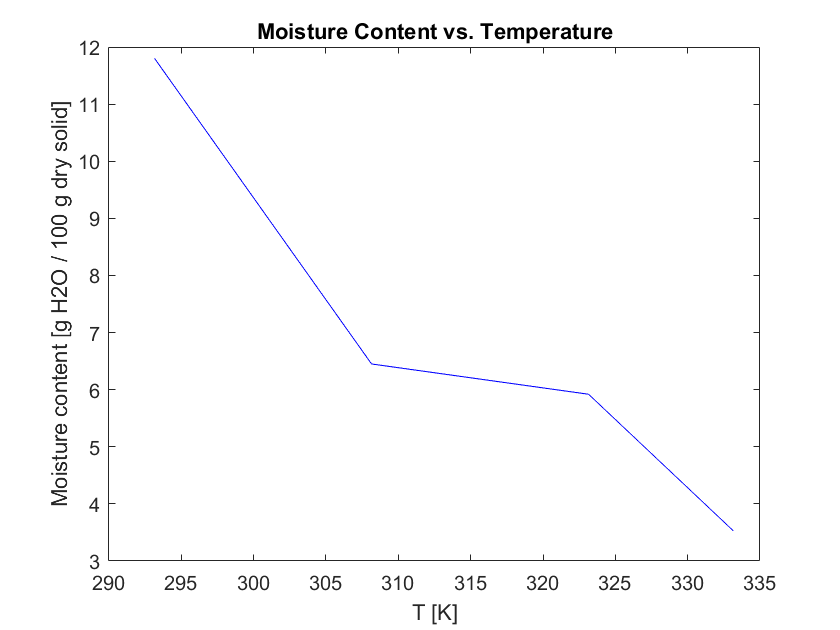

figure
plot(Temp, Mo);
title('Moisture Content vs. Temperature')
xlabel('T [K]')
ylabel('Moisture content [g H2O / 100 g dry solid]')

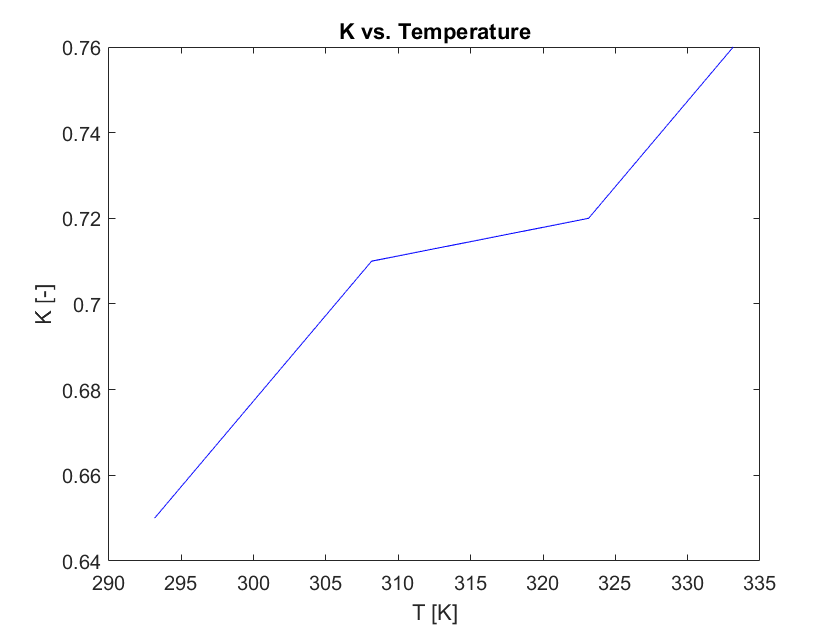

figure
plot(Temp, K);
title('K vs. Temperature')
xlabel('T [K]')
ylabel('K [-]')

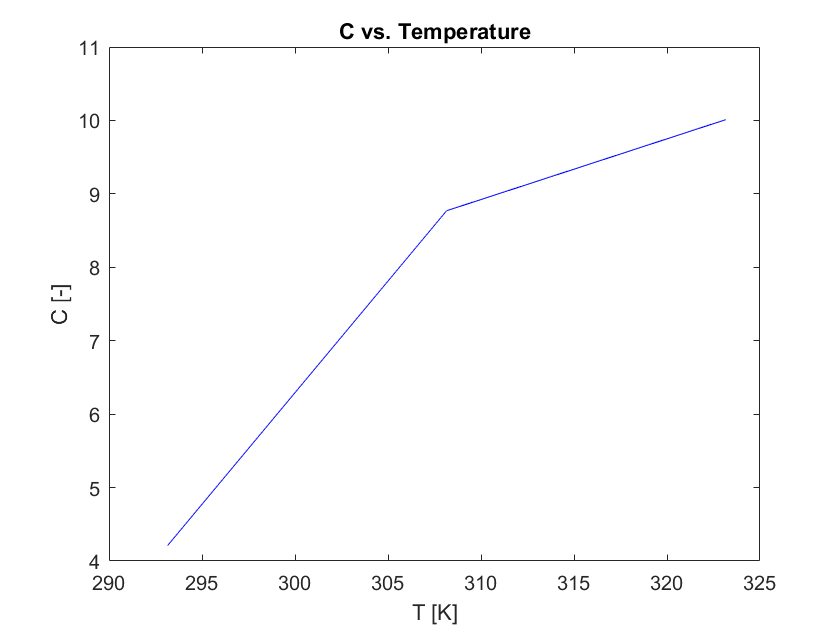

figure
plot(Temp(:,1:3), C);
title('C vs. Temperature')
xlabel('T [K]')
ylabel('C [-]')

This section calculates estimated parameters for K, C, and Mo equations as functions of temperature and plots the linear fits to the data.

**Equation 1:** $m=m_0 e^{\frac{-\Delta H_m }{\mathrm{RT}}}$

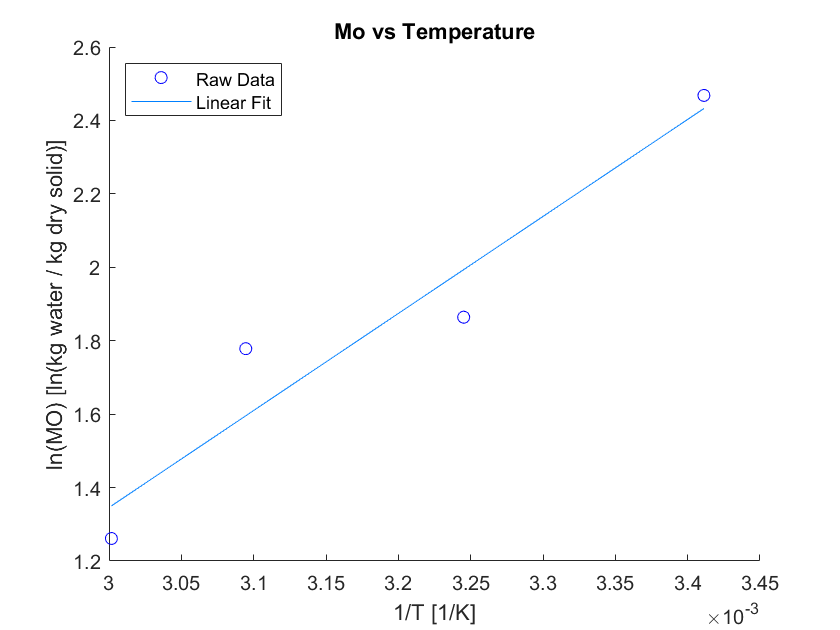

R = 8.314; %universal gas constant J/mol*K

figure()
hold on
scatter(1./Temp, log(Mo),'DisplayName','Raw Data');
X = [1./Temp;ones(1,length(1./Temp))];
linear_coef_mo = polyfit((1./Temp), (log(Mo)), 1);
plot(1./Temp, linear_coef_mo(2) + linear_coef_mo(1).*(1./Temp),'DisplayName','Linear Fit')
legend('show', 'Location', 'northwest');
title('Mo vs Temperature')
xlabel('1/T [1/K]');
ylabel('ln(MO) [ln(kg water / kg dry solid)]');

**Equation 2: **$k=k_0 e^{\frac{-\Delta H_k }{\textrm{RT}}}$

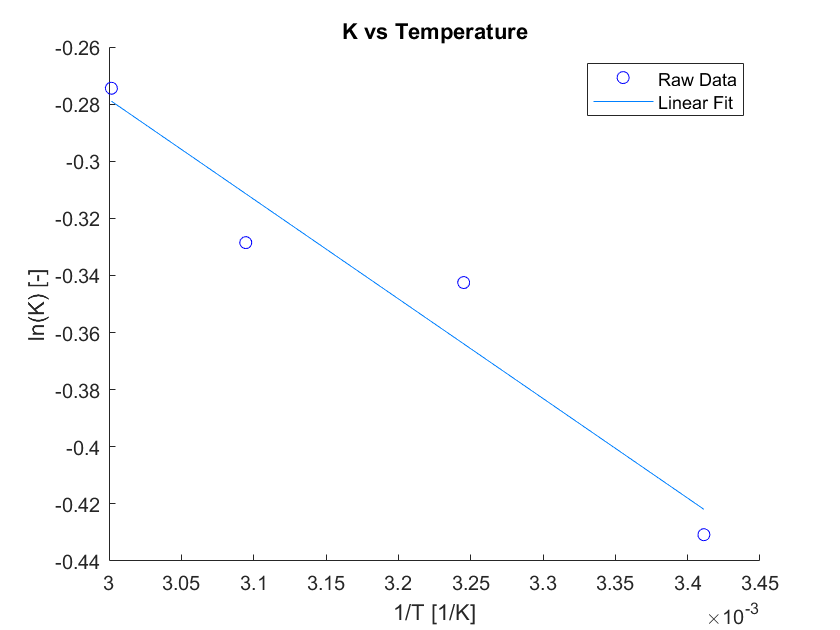

figure()
hold on
scatter(1./Temp, log(K),'DisplayName','Raw Data');
X = [1./Temp;ones(1,length(1./Temp))];
linear_coef_K = polyfit((1./Temp), (log(K)), 1);
plot(1./Temp, linear_coef_K(2) + linear_coef_K(1).*(1./Temp),'DisplayName','Linear Fit')
legend('show');
title('K vs Temperature')
xlabel('1/T [1/K]');
ylabel('ln(K) [-]');

**Equation 3: **$c=c_0 e^{\frac{-\Delta H_c }{\textrm{RT}}}$

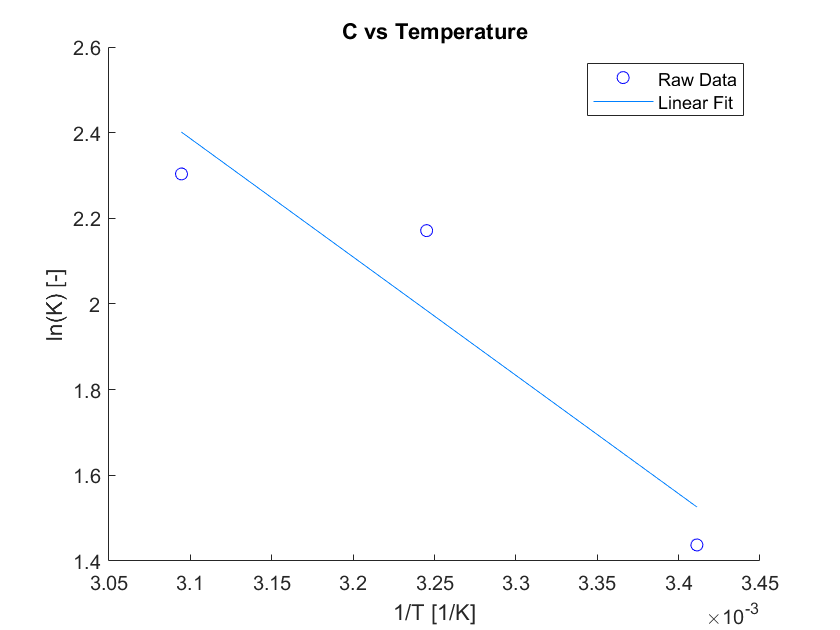

figure()
hold on
scatter(1./Temp(1:3), log(C),'DisplayName','Raw Data');
X = [1./Temp(1:3);ones(1,length(1./Temp(1:3)))];
linear_coef_C = polyfit((1./Temp(1:3)), (log(C)), 1);
plot(1./Temp(1:3), linear_coef_C(2) + linear_coef_C(1).*(1./Temp(1:3)),'DisplayName','Linear Fit')
legend('show');
title('C vs Temperature')
xlabel('1/T [1/K]');
ylabel('ln(K) [-]');

This section calculates moisture contents for various temperatures and water activities.

**Equation 4: **$\frac{m}{m_0 }=\frac{c\cdot k\cdot \alpha_w }{\left(1-k\cdot \alpha_w \right)\left(1+\left(c-1\right)k{\cdot \alpha }_w \right)}$

M_major = [];
Temperature = (5+273):0.1:(110+273);
step = 1/length(Temperature);
aw = 0:step:1;
figure
hold on

for i = 1:length(Temperature)
    Mo_new = exp(linear_coef_mo(2))*exp(linear_coef_mo(1)/Temperature(i));
    C_new =  exp(linear_coef_C(2))*exp(linear_coef_C(1)/Temperature(i));
    K_new = exp(linear_coef_K(2))*exp(linear_coef_K(1)/Temperature(i));
    for j = 1:length(aw)
        M(j) = (Mo_new*C_new*K_new*aw(j))/((1-K_new*aw(j))*(1+(C_new-1)*K_new*aw(j)));
        M_major(i,j) = M(j);
    end
    if (rem(Temperature(i),10) == 0)
        plot(aw,M)
    end
end
title('Moisture Content vs Water Activity')
xlabel('Water Activity [-]');
ylabel('Moisture Content [kg water / kg dry solid]');
legend('10 C','20 C','30 C','40 C','50 C','60 C','70 C','80 C', '90 C','100 C','110 C', 'Location', 'northwest')

### Determine Eb as a function of moisture content and temperature.  Plot Eb vs moisture at various temperatures.

This section calculates water activities from moisture content range using backsolved GAB equation.

**Equation 5: **$E_b =\mathrm{ln}\left(\frac{\alpha_{w_2 } }{\alpha_{w_1 } }\right)\frac{R}{{\left(\frac{1}{T_1 }-\frac{1}{T_2 }\right)}_M }$

M_test = [0:0.01:30];
aw_isotherm = [];
Eb_major = [];

for i = 1:length(M_test)
    for j = 1:length(Temperature)
        Mo_temp = exp(linear_coef_mo(2))*exp(linear_coef_mo(1)/Temperature(j));
        C_temp =  exp(linear_coef_C(2))*exp(linear_coef_C(1)/Temperature(j));
        K_temp = exp(linear_coef_K(2))*exp(linear_coef_K(1)/Temperature(j));
        aw_isotherm(i,j) = (2 + ((Mo_temp/M_test(i))-1)*C_temp - ((2+(Mo_temp/M_test(i)-1)*C_temp)^2 - 4*(1-C_temp))^0.5)/(2*K_temp*(1-C_temp));
    end
end

This section calculates binding energies based off of water activities and temperatures

for i = 1:length(M_test)
    for j = 1:length(Temperature)-1
        Eb(j) = log(aw_isotherm(i,j+1)/aw_isotherm(i,j))*R/((1/Temperature(j)) - (1/Temperature(j+1)));
        Eb_major(i,j) = Eb(j);
    end
end

This section plots binding energy data.

figure()
hold on
plot(M_test,Eb_major(:,1))
plot(M_test,Eb_major(:,11))
plot(M_test,Eb_major(:,21))
plot(M_test,Eb_major(:,31))
plot(M_test,Eb_major(:,41))
plot(M_test,Eb_major(:,51))
title('Eb vs M at Various Temperatures')
xlabel('Moisture Content (%)');
ylabel('Binding Energy (J/mol)')
legend('5 C','15 C','25 C','35 C','45 C', '55 C')

### Determine Deff from Eq 48 of the Food Dehydration chapter (10).  Calculate Ea, Do (liquid water), Do (vapor water), from Diffusivity data at different temperatures given Geankoplis or other literature. Use K as given in Chp 10 p 661.  Compare calculated Deff with Deff values found in literature.  Plot Deff vs. moisture at various temperatures and plot Deff vs. moisture at various porosities.  Compare with data given in Chp 10 Table 10.7. 

This section determines Deff Vs M at different temperatures and constant porosity.

**Equation 6:** $D_{\mathrm{AVeff}} =\frac{\varepsilon }{\tau }D_{\mathrm{AV}} =\frac{\varepsilon }{\tau }\left(D_{\mathrm{AVD}} e^{\frac{-E_c }{R\;T}} \right)=\frac{\varepsilon }{\tau }\left(D_{\mathrm{AVO}} e^{\frac{-E_A }{R\;T}} \right)\frac{Ke^{\frac{-E_b }{R\;T}} }{1+Ke^{\frac{-E_b }{R\;T}} }$

**Equation 7: **$D_{\mathrm{ALeff}} =\frac{1-\varepsilon }{\tau }D_{\mathrm{AL}} =\frac{1-\varepsilon }{\tau }\left(D_{\mathrm{ALD}} e^{\frac{-E_A }{R\;T}} \right)$=$\frac{1-\varepsilon }{\tau }\left(D_{\textrm{ALO}} e^{\frac{-E_A }{R\;T}} \right)$$\frac{Ke^{\frac{-E_b }{R\;T}} }{1+Ke^{\frac{-E_b }{R\;T}} }$

**Equation 8:** = $D_{\mathrm{eff},\mathrm{series}} =\frac{\varepsilon }{\tau }D_V +\frac{1-\varepsilon }{\tau }D_L$

**Equation 9: **$\frac{1}{D_{\mathrm{eff},\mathrm{perpendicular}} }=\frac{1}{\frac{\varepsilon }{\tau }D_V }+\frac{1}{\frac{1-\varepsilon }{\tau }D_L }$

**Equation 10: **$D_{\mathrm{eff}} =\varphi D_{\mathrm{eff},\mathrm{series}} +\left(1-\varphi \right)D_{\mathrm{eff},\mathrm{perpendicular}}$

porosity = 0.5;
tau = 1.5;
phi = 0.5;
Davo = 2*10^-5;
Dalo = 1*10^-9;
Ea = 5.2*4.184;
K = 0.9;

This section calculates the general diffusivity for various temperatures and moisture contents. 

for i = 1:length(M_test)
    for j = 1:length(Temperature)-1
        %vapor
        DAVeff(i,j) = Davo*(exp(-Ea/(R*Temperature(j))))*(K*(exp(-Eb_major(i,j)/(R*Temperature(j))))) ...
            /(1 + (K*exp(-Eb_major(i,j)/(R*Temperature(j)))));
        %liquid
        DALeff(i,j) = ((Dalo*exp(-Ea/(R*Temperature(j))))*(K*exp(-Eb_major(i,j)/(R*Temperature(j)))) ...
            /(1 + (K*exp(-Eb_major(i,j)/(R*Temperature(j))))));
        %diffusivity in series
        Dserieseff(i,j) = (porosity/tau)*DAVeff(i,j) + ((1-porosity)/tau)*DALeff(i,j);
        %diffusivity perendicular to material
        Dperpeff(i,j) = ((1/((porosity/tau)*DAVeff(i,j))) + (1/(((1-porosity)/tau)*DALeff(i,j))))^-1;
        %total diffusivity
        Deff(i,j) = phi*Dserieseff(i,j) + (1-phi)*Dperpeff(i,j);
    end
end

This section plots the diffusivity data

figure()
hold on
plot(M_test,Deff(:,1),M_test,Deff(:,11),M_test,Deff(:,21),M_test,Deff(:,31),M_test,Deff(:,41),M_test,Deff(:,51))
title({'Diffusivity verses Moisture Content @ Different', 'Temperatures and Constant Porosity'})
xlabel('Moisture Content (%)')
ylabel('Diffusivity (m^2/s)')
legend('5 C','15 C','25 C','35 C','45 C', '55 C')

This section determines Deff vs M at different porosities and constant temperature

Temp_constant = 25+273.15;
Eb_at_temp_const = Eb_major(:,51).';
porosities = 0.1:0.1:0.9;

This section calculates general diffusivity at constant temperature

for i = 1:length(M_test)
    for j = 1:length(porosities)
        %vapor
        p_DAVeff(i,j) = Davo*exp(-Ea/(R*Temp_constant))*((K*exp(-Eb_at_temp_const(i)/(R*Temp_constant))) ...
            /(1 + (K*exp(-Eb_at_temp_const(i)/(R*Temp_constant)))));
        %liquid
        p_DALeff(i,j) = (Dalo*exp(-Ea/(R*Temp_constant)))*((K*exp(-Eb_at_temp_const(i)/(R*Temp_constant))) ...
            /(1 + (K*exp(-Eb_at_temp_const(i)/(R*Temp_constant)))));
        %diffusivity in series with various porosities
        p_Dserieseff(i,j) = (porosities(j)/tau)*p_DAVeff(i,j) + ((1-porosities(j))/tau)*p_DALeff(i,j);
        %diffusivity perpendicular to material with various porosities
        p_Dperpeff(i,j) = ((1/((porosities(j)/tau)*p_DAVeff(i,j))) + (1/(((1-porosities(j))/tau)*p_DALeff(i,j))))^-1;
        %total diffusivity
        p_Deff(i,j) = phi*p_Dserieseff(i,j) + (1-phi)*p_Dperpeff(i,j);
    end
end

This section plots the diffusivity data

figure()
hold on
plot(M_test,p_Deff(:,1),M_test,p_Deff(:,2),M_test,p_Deff(:,3),M_test,p_Deff(:,4),M_test,p_Deff(:,5),M_test,p_Deff(:,6),M_test,p_Deff(:,7),M_test,p_Deff(:,8),M_test,p_Deff(:,9))
title({'Diffusivity verses Moisture Content at Different', 'Porosities and Constant Temperature (25 C)'})
xlabel('Moisture Content [kg water / kg dry solid]')
ylabel('Diffusivity [m^2/s]')
legend('porosity = 0','porosity = 0.1','porosity = 0.2','porosity = 0.3','porosity = 0.4', 'porosity = 0.5','porosity = 0.6','porosity = 0.7','porosity = 0.8','porosity = 0.9')

## Part B: Determine the dryer operating conditions (temperature and humidity) maximize shrinkage to dehydrate the dry product form 60% H2O wb to 10% H2O wb.

### Plot Tg as a funciton of moisture ocntent using the Fox equation and determine the temperature and humidity for one stage of the dryer. Tg of the dry solid is 410K and Tg of water is 134 K.

**Single-Stage Dryer:**

Tg_solid = 410; %Kelvin
Tg_water = 134; %Kelvin
M_range = 0:0.001:0.9;

This section calculates Tg data for the product

for i = 1:length(M_range)
    Tg_original(i) = ((M_range(i)/Tg_water) + ((1-M_range(i))/Tg_solid))^-1;
end

This section plots the Tg data

 figure()
 hold on
 plot(M_range,Tg_original)
 title('Glass Transition Temperature versus Moisture Content')
 xlabel('Moisture Content (decimal)')
 ylabel('Temperature K')

This section finds the Tg data 10 and 30 degrees above normal, which is used for final graph as reference data

Tg_30 = Tg_original + 30;
Tg_10 = Tg_original + 10;
Mc_initial = 0.4; % changed to Part 2 Value
Mc_desired = 0.05;

This line sets temporary variable for moisture content to initial moisture content

Mc_final = 0.6;

This line sets the initial Tg graph to the original Tg data

Tg_initial = Tg_original;
stages = [1 0.6;0 0];
i = 2;
temp_change = Tg_10(Mc_desired*1000+1) - Tg_10(Mc_initial*1000+1);
Tg_op = Tg_original + temp_change;
Operating_Temperature = Tg_op(Mc_desired*1000+1);
Mo_temp = exp(linear_coef_mo(2))*exp(linear_coef_mo(1)/Operating_Temperature);
C_temp = exp(linear_coef_C(2))*exp(linear_coef_C(1)/Operating_Temperature);
K_temp = exp(linear_coef_K(2))*exp(linear_coef_K(1)/Operating_Temperature);
RH = (2 + ((Mo_temp/10)-1)*C_temp - ((2+(Mo_temp/10-1)*C_temp)^2 - 4*(1-C_temp))^0.5)/(2*K_temp*(1-C_temp));
RH = RH*100;
fprintf('For a one stage dryer, the operating temperature must be %.2f K and the RH must be %.2f%%.',Operating_Temperature,RH)

**Multi-Stage Dryer**

### The drying process is to be designed to produce a dense product by maintaining the surface conditions at least 10C above the Tg.

This section sets temperature range to be tested in optimization process

op_temp_range = (round(Tg_original(Mc_initial*1000+1),0)+10)+1:0.1:(round(Tg_original(Mc_initial*1000+1),0)+40);
mc_in = []; %array to hold all initial moisture content values per stage
mc_out = [];%array to hold all final moisture content values per stage
final_mc_values = [0 0;0 0];% array to hold final moisture contents for all tested temperatures along with the number of stages required for each temperature to reach Mc = 0.1
RH_values = []; %array to hold all relative humidity values for each iteration
stage_op_temps = []; %array to hold all stage operation temperatures per iteration

for i = 1:length(op_temp_range)
    %stores operating temerature
    final_mc_values(i,1) = op_temp_range(i);
    %creates new Tg curve based off operating temeprature
    Tg_op_temp = Tg_original + (op_temp_range(i)-Tg_original(Mc_initial*1000+1));
    %initiaizes temp moisture content variable to initial moisture content
    Mc_final = Mc_initial;
    stages_temp = [1 0.6;0 0]; %temp v
    j = 2;%counter and indexer for outside arrayw during while loop
    while Mc_final > Mc_desired
        mc_in(i,j) = Mc_final;    %store initial moisture content of stage
        Op_temp_index = Mc_final*1000+1; %set index for operating temperature
        Op_Temp = Tg_op_temp(Op_temp_index); %find operating temperature to use
        stage_op_temps(i,j-1) = Op_Temp; %store operating temperature
        Mo_temp = exp(linear_coef_mo(2))*exp(linear_coef_mo(1)/Op_Temp); %find Mo
        C_temp =  exp(linear_coef_C(2))*exp(linear_coef_C(1)/Op_Temp); %find C
        K_temp = exp(linear_coef_K(2))*exp(linear_coef_K(1)/Op_Temp);% find K
        %calculate new moisture content using backsolved FOX equation
        Mc_final = round(Tg_water*(Tg_solid - Op_Temp + 10)/((Op_Temp-10)*(Tg_solid - Tg_water)),3);
        stages_temp(j,1) = j;
        stages_temp(j,2) = Mc_final;
        mc_out(i,j) = Mc_final; %stores final moisture content of cycle
        %calculates relative humidity required for cycle
        RH_stage = (2 + ((Mo_temp/(Mc_final*100))-1)*C_temp - ((2+(Mo_temp/(Mc_final*100)-1)*C_temp)^2 - 4*(1-C_temp))^0.5)/(2*K_temp*(1-C_temp));
        RH_stage = RH_stage*100;
        RH_values(i,j) = round(RH_stage); %stores relative humidity value
        stages_temp(j-1,3) = RH_stage;
        j = j+1;
    end
    final_mc_values(i,2) = stages_temp(length(stages_temp),2); %stores final moisture content of stage
    final_mc_values(i,3) = j-2; %stores number of stages required for operating temperature
end

This line finds all operating temperatures that give a final moisture content of 0.05

optimal_temp_values(1,:) = op_temp_range(find(final_mc_values(:,2)==Mc_desired));

This line finds the number of stages needed for operating temperatures searched above

optimal_temp_values(2,:) = final_mc_values(find(final_mc_values(:,2) == Mc_desired),3);

This line calculates the index for the optimal operating temperature for deisgn (highest temperature with the lowest number of cycles)

optimal_temperature_index = find(op_temp_range == optimal_temp_values(1, length(optimal_temp_values)));

This line finds the inital moisture contents for the optimal temperature.

mc_in_final = mc_in(optimal_temperature_index,:);

This line finds the final moisture contents for the optimal temperature.

mc_out_final =  mc_out(optimal_temperature_index,:);

This line finds the operating temperatures for each stage in iteration of optimal operating temperature.

optimal_op_temp_values = stage_op_temps(optimal_temperature_index,:);

This line finds relative humidities for each stage in iteration of optimal operating temperature

optimal_RH_values = RH_values(optimal_temperature_index,:);
stage_number = optimal_temp_values(2,length(optimal_temp_values));
fprintf('Multi-Stage Dryer Operating Conditions:\n');
for i = 1:stage_number
    fprintf('Stage %d   Operating Temperature: %.2f K   RH: %d percent   MC_in = %.2f   MC_out = %.2f\n',i,optimal_op_temp_values(i),optimal_RH_values(i+1),mc_in_final(i+1),mc_out_final(i+1));
end

This section plots the multi stage drying process

figure()
hold on
plot(M_range,Tg_original,M_range,Tg_original+10,M_range, Tg_original+40,M_range, Tg_original+(optimal_op_temp_values(1)-Tg_original(Mc_initial*1000+1)))
for i = 1:stage_number
    plot([mc_out_final(i+1),mc_in_final(i+1)],[optimal_op_temp_values(i),optimal_op_temp_values(i)])
end
title('Multi-Stage Dryer Stage Process')
xlabel('Moisture Content (decimal)')
ylabel('Temperaature (K)')
legend('Tg','Tg+10','Tg+40','Operating Tg')

## Problem:

Design a through-circulation conversion dryer to produce a non-porous product. 

### Dryer Design Requirements

- Electrical and steam loads

- Air temperature and RH for each section

- length of each section

- fan size for each section -- airflow, pressure drop, Hp

- Heat exchanger design for each section

### Equipment and utility costs are as follows:

- Fan: Cfan = $10000[V(m^3/min)/30]^0.54

- Air-cooled HX: Chx = $10000[BareArea(m^2)/10]^0.6

- Conveyer: Ccon = $60000[L(m)/60]^0.85

- Steam: $5/1000 lb.

- Electricity: $0.10/kWh

### Dryer Design Requirements

- Electrical and steam energy requirement

- Air temperature and relative humidity for each section

- Belt width for entire dryer 8 ft

- Length of each section

- Fan size for each section

- Heat exchanger design for each section

### General Requirements

- Minimize the energy consumption

- Maximize product quality. Comment on the expected quality changes (shrinkage, and glatinization of pasta during drying)

### References:

- Perry's Chemical Engineer's Handbook

- Geankoplis

- Conveyer Dryers in Handbook of Industrial Drying, Chap. 15

- Plant Design an Economics Petr, Timmerhaus and West

### Part A: 

Design a continuous through-circulation conveyer dryer to produce 2000 kg/hr of a dense extruded couscous product from 40% to 5% wb moisture content. The initial diameter 5 mm.  The dryer has to be as energy efficient as possible.  The dryer is composed of several sections at different air temperatures and air humidities to produce the desired texture.  Drying air can be transferred to the outside or between sections.  Air is heated by passing over banks of finned coils containing steam available at 100 psig.

initial_diameter = 0.005; %[m] initial diameter of cylinder in packed bed
radii = initial_diameter / 2; %[m] radius of cylinders in each stage
stage_diffusions = []; %[m^2/s] average diffusivity coefficients for each stage
width = 2; % [m] width of the conveyer belt within the dryer

for i = 1:stage_number
    average_mc(i) = round((mc_in_final(i+1)+mc_out_final(i+1))/2,2); % average moisture content of drying stage
    operating_temp = round(optimal_op_temp_values(i),1); % [K] operating temperature for the drying stage
    dry_comp = [average_mc(i) (1-average_mc(i))*0.5294 (1-average_mc(i))*0.1176 (1-average_mc(i))*0.2353 ...
        (1-average_mc(i))*0.1176 (1-average_mc(i))*0.0001]; %composition of extruder dry product
    product_density(i) = rhonew(dry_comp,[1 2 3 4 5 6],operating_temp); %[kg/m^3] density of dry product
    mc_equilibrium(i) = Tg_water*(Tg_solid-operating_temp)/(operating_temp*(Tg_solid-Tg_water)); %equilibrium moisture content of the dryer stage
    stage_diffusions(i) = Deff(find(M_test == round(average_mc(i)*100)),find(Temperature == operating_temp)); %[m^2/s] average diffusivity coefficient for the dryer stage
    t = (4*radii(i)^2/(pi^2*(stage_diffusions(i)/1000)))*log((8*(mc_in_final(i+1)-mc_equilibrium(i)))/(pi^2*(mc_out_final(i+1)-mc_equilibrium(i))));% [s] residence time of dry product for the dryer stage
    residence_times(i) = t;
    volume_rate_in = (2850/(1-mc_in_final(i+1)))/product_density(i); %[m^3/s] volumetric flow rate of dry product in
    volume_rate_out = (2850/(1-mc_out_final(i+1)))/product_density(i); %[m^3/s] volumetric flow rate of dry product out
    volume_lost(i) = (volume_rate_in - volume_rate_out)*t; %[m^3] volume of water lost from product
    volume_total(i) = volume_rate_in*t; %[m^3] volume of dry product coming in the dryer
    vol_lost_cyl = (volume_lost(i)/volume_total(i))*vol_cyl; %[m^3] volume lost from a single cylinder part of dry product
    vol_cyl = vol_cyl - vol_lost_cyl; %[m^3] volume of new cylinder
    radii(i+1) = (vol_cyl/(pi*height))^(1/2); %[m] new cylinder radius
    Ls(i) = (2850/(1-mc_in_final(i+1)))*(residence_times(i)/3600); %[kg] mass of dry product coming into dryer
    A(i) = Ls(i) / (product_density(i)*height); % [m^2] cross sectional area of dry product in dryer
    section_length(i) = A(i)/width; %[m] length of dry product in dryer
    conv_vel(i) = section_length(i) / (residence_times(i)); %[m/s] velocity of conveyor to achieve appropriate amount of dry product dried within residence time
end

This section finds the drying rate as a function of free moisture content

mc_final = [mc_in_final(2)];
for i= 2:stage_number+1
    mc_final(i) = mc_out_final(i);
end

for i = 1:stage_number
    drying_rates(i) = (pi^2*product_density(i)*(stage_diffusions(i)*1000)*(average_mc(i)-mc_equilibrium(i)))/(4*radii(i));
end

mc_final(length(mc_final)) = [];
figure()
plot(mc_final,drying_rates)
mc_final(length(mc_final)+1) = mc_out_final(stage_number+1);
title('Drying Time as a Function of Moisture Content')
xlabel('Moisture Content [kg water / kg dry weight]')
ylabel('Drying Rate [kg H20/hr-m^2]')

This section calculates the pressure drop and gas flow rate

porosity = 0.5;
air_velocities = [];
pressure_drops = [];
ks = [0.00707 0.00701 0.00697 0.00692]; %thermal conductivity for solid
vapor_k = [0.0256 0.0273 0.0269 0.0255]; %thermal conductivity for vapor
lengths = [radii(1)*20 radii(2)*20 radii(3)*20 radii(4)*20];
cpair = [1.0049 1.0063 1.0082 1.0106];
Humidities = [0.01228 0.06943 0.38611 1.84998]; %absolute humidities for beginning moisture contents for stages
Sherwood = 15;

for i = 1:stage_number
    %Mass Transfer Coefficient
    k_prime_c(i) = Sherwood*stage_diffusions(i)/(2*radii(i));
    Mass_flow_in(i) = (2850/(1-mc_final(i)));
    Mass_flow_out(i) = (2850/(1-mc_final(i+1)));
    G(i) = ((Mass_flow_out(i) - Mass_flow_in(i))/(-0.1*(optimal_RH_values(i+1)/100)))/(3600);
    rho(i) = rhoair(optimal_op_temp_values(i),0.101325);
    cp_moist(i) = (1.005 + 1.88*(Humidities(i)))*1000;
    %Moist Air Density Calculations
    total_air_vol(i) = G(i)*residence_times(i);
    dry_air_mass_kg(i) = total_air_vol(i)*rho(i);
    wet_air_vol(i) = volume_lost(i);
    sat_partial_pressure(i) = exp(77.345 + 0.0057*optimal_op_temp_values(i) -(7235/optimal_op_temp_values(i)))/(optimal_op_temp_values(i)^8.2);
    vapor_partial_pressure(i) = (optimal_RH_values(i+1)/100)*sat_partial_pressure(i);
    vapor_density = (0.0022*vapor_partial_pressure(i))/optimal_op_temp_values(i);
    wet_air_mass_kg(i) = wet_air_vol(i)*vapor_density;
    humidity_ratio(i) = wet_air_mass_kg(i)/dry_air_mass_kg(i);
    moist_air_density(i) = rho(i)*(1+humidity_ratio(i))/(1 + 1.1609*humidity_ratio(i));
    %Air Viscosity
    mu = muair(optimal_op_temp_values(i));
    %Air Velocity
    air_velocity = (((mu/moist_air_density(i)*2*radii(i)*porosity)^-0.4069)*porosity*(k_prime_c(i)/0.4549)*((mu/(moist_air_density(i)*stage_diffusions(i)))^(2/3))^(1-0.4069))/10;
    air_velocities(i) = air_velocity; 
    %Pressure Drop
    pressure_drop = (150*mu*moist_air_density(i)*air_velocity*(height)/(2*radii(i))^2)*(((1-porosity)^2)/porosity^3) + ((1.75*moist_air_density(i)*(air_velocity^2)*(height))/(2*radii(i)))*(((1-porosity))/porosity^3)/10;
    pressure_drops(i) = pressure_drop;
    %Air Flow Rate
    wet_flow_air_rate(i) = air_velocity*(section_length(i)*width)*moist_air_density(i)/100;
end


This section calculates the fan horsepower and power requirements

for i = 1:stage_number
    pressure_head = pressure_drops(i)*0.0986923*101325;
    velocity_head = (air_velocities(i)^2)/2;
    Ws = pressure_head+velocity_head;
    fan_eff = 0.7;
    kW(i) = Ws*(wet_flow_air_rate/moist_air_density(i))/(fan_eff*1000);
    hp = kW*1.34102;
end

This section calculates the temperature drop

lambda = 2501;
Tin = optimal_op_temp_values(1);
delT(1) = 0;

This section finds the temperature change for the solid

for i = 2:stage_number
    delT(i) = optimal_op_temp_values(i) - optimal_op_temp_values(i-1);
end

This section finds the Cp values

dry_comp = [0.5294 0.1176 0.2353 0.1176 0.0001];
cp_water = 4.184;
for i = 1:stage_number
    cs(i) = (1.005+1.88*Humidities(i))*1000;
    cp_solid(i) = (cpnew(dry_comp(1),dry_comp(2),dry_comp(3),dry_comp(4),dry_comp(5),optimal_op_temp_values(i)))*1000;
end

This section calculates the energy balance for the temperature drop

for i = 1:stage_number
    massair(i) = G(i)*residence_times(i)*3600;
    mass_vapor(i) = abs((wet_flow_air_rate(i)-G(i))*residence_times(i)*3600);
    mass_solid(i) = 2850*residence_times(i);
    mass_water(i) = Mass_flow_out(i)*mc_final(i+1)*residence_times(i);
    mass_water_evap(i) = (Mass_flow_in(i) - Mass_flow_out(i))*residence_times(i);
    Temp_out(i) = optimal_op_temp_values(i) - ((mass_solid(i)*cp_solid(i)*delT(i) + mass_water(i) ...
        *cp_water*delT(i) + mass_water_evap(i)*(lambda + Eb_major(find(M_test == round(average_mc(i)*100,2)),find(Temperature == round(optimal_op_temp_values(i),1)))) ...
        -mass_water_evap(i)*cp_water*delT(i))/(massair(i)*cs(i) + mass_vapor(i)*cp_water))/100;
    temp_drop(i) = abs(optimal_op_temp_values(i)-Temp_out(i)); 
end

This section calculates the fraction of recycled air going back to the heater the temperature into the heat exchanger.

Humid_out = [0.01351 0.07637 0.42473 2.03498];
H_fresh = 0.00998;
cs_fresh = (1.005+1.88*H_fresh)*1000;
Temp_fresh = 25+273.17;
for i = 1:stage_number
    cs_out(i) = (1.005+1.88*Humid_out(i))*1000;
    %Fraction of recycled air going into heat exchanger
    X_fraction(i) = (Humidities(i)*G(i) - H_fresh*G(i))/(Humid_out(i)*G(i) - H_fresh*G(i));
    temp_in_he(i) = (-cs_fresh*X_fraction(i)*Temp_fresh + cs_fresh*Temp_fresh + Temp_out(i)*cs_out(i)*X_fraction(i)) ...
        /(cs_fresh*(-X_fraction(i)) + cs_fresh + cs_out(i)*X_fraction(i)); 
end

### Heat Exchanger Design

steam_density = 3.667; %[kg/m^3] density of steam from Engineering Toolbox
steam_velocity = 11.6; %[m/s] velocity of setam found from CJG Table 2.10-3 for a steel pipe
cp_steam = 2.4424*1000; %[j/kg-K] specific heat capacity of steam found in Engineering ToolBox

steam_vol_flow_rate = steam_velocity*Cross_sectional_area; %[m^3/s] volumetric flow rate of steam through steel pipe
steam_mass_flow_rate = steam_vol_flow_rate*steam_density; %[kg/s] mass flow rate of steam through steel pipe

delta_temp_steam = 5; %[K] tunable change of steam temperature while heating the heat exchanger
Q_steam = steam_mass_flow_rate*cp_steam*delta_temp_steam; %[W] heat applied to heat exchanger from steam

for i = 1:stage_number
    delta_temp_heater(i) = abs(optimal_op_temp_values(i) - temp_in_he(i)); %[K] change in temperature in the heat exchanger
    ho(i) = (10.45 - air_velocities(i) + 10*air_velocities(i)^0.5)*10; %[W/m^2-K] air convection coefficient from Engineering ToolBox
end

### Dryer Design Cost

Fan Cost (per minute)

fan_cost = 10000 * ((steam_vol_flow_rate * 60) / 30) ^ 0.54;

Air Cooling Cost

air_cool_hx_cost = 10000 * (8 * sum(section_length) / 10) ^ 0.6;

Conveyer Cost

conveyer_cost = 60000 * (sum(section_length) / 60) ^ 0.85;

Steam Cost (per minute)

steam_lbs = steam_mass_flow_rate * 60 * 2.2;
steam_cost = 5 / 1000 * steam_lbs;

Electricity Cost (per minute)

electricity_cost = 0.10 * sum(kw) / 60;

Total Fixed Cost

total_fixed_cost = air_cool_hx_cost + conveyer_cost;

Total Additional Cost Per Minute

total_cost_per_min = fan_cost + steam_cost + electricity_cost;
total_cost_per_hour = total_cost_per_min * 60;
total_cost_per_day = total_cost_per_hour * 24;
total_cost_per_year = total_cost_per_day * 365;
fprintf('The total fixed cost of the dryer is $%.2f.\nThe total additional cost per year of the dryer is $%.2f.\nThe total cost of the dryer for the first year is $%.2f.',total_fixed_cost,total_cost_per_year,total_fixed_cost+total_cost_per_year)

## Sub-Functions

function [Frho] =  rhonew(Fcomp,Fctype,FtempK)
    %     Reference temperture (K)
    Tref = 273.15;
    %     Convert T (K) to T (C)
    TC = FtempK - Tref;
    for I = 1:length(Fcomp)
        if (Fctype(I) == 1)
            %         Density of water component (kg/m^3)
            rhoh20 = 997.18 + 0.0031439*TC - (0.0037574)*(TC^2);
            %         Weighted specific volume of water component (m^3/kg)
            Fcsv(I) = Fcomp(I)/rhoh20;
        elseif (Fctype(I) == 2)
            %         Density of protein component (kg/m^3)
            rhopro = 1329.9 -0.5184*TC;
            %         Weighted specific volume of protein component (m^3/kg)
            Fcsv(I) = Fcomp(I)/rhopro;
        elseif (Fctype(I) == 3)
            %         Density of carbohydrate component (kg/m^3)
            rhocarb = 1599.1 - 0.31046*TC;
            %         Weighted specific volume of carbohydrate component (m^3/kg)
            Fcsv(I) = Fcomp(I)/rhocarb;
        elseif (Fctype(I) == 4)
            %         Density of fiber component (kg/m^3)
            rhofiber = 1311.5 - 0.36589*TC;
            %         Weighted specific volume of fiber component (m^3/kg)
            Fcsv(I) = Fcomp(I)/rhofiber;
        elseif (Fctype(I) == 5)
            %         Density of fat component (kg/m^3)
            rhofat = 925.59 - 0.41757*TC;
            %         Weighted specific volume of fat component (m^3/kg)
            Fcsv(I) = Fcomp(I)/rhofat;
        elseif (Fctype(I) == 6)
            %         Density of ash component (kg/m^3)
            rhoash = 2423.8 - 0.28063*TC;
            %         Weighted specific volume of ash component (m^3/kg)
            Fcsv(I) = Fcomp(I)/rhoash;
        end
    end
    %     Density of stream weighted by compositional breakdown (kg/m^3)
    Frho = 1.0/sum(Fcsv);
end

function [denair] = rhoair(Tair,Pair)
    %     Gas law constant (kg-m^2/s^2-kgmol-K)
    R = 8314.34;
    %     Molecular weight of air (kg/kgmol)
    MWair = 28.97;
    %     Specific volume of air (m^3/kg)
    vair = R*Tair/(MWair*Pair*1e6);
    %     Density of air (kg/m^3)
    denair = 1.0/vair;
end

function [visair] = muair(Tair)
    %     Temperature data (K)
    T = [255.4; 273.2; 283.2; 311.0; 338.8; 366.5;
        394.3; 422.1; 449.9; 477.6; 505.4; 533.2;];
    %     Viscosity data (Pa-s*10^5)
    mu = [1.62; 1.72; 1.78; 1.90; 2.03; 2.15;
        2.27; 2.37; 2.50; 2.60; 2.71; 2.80;];
    %     Viscosity (Pa-s)
    mu = mu*1e-5;
    %     Use temperature (K) to find viscosity (Pa-s) in a
    %     1D-look-up table.
    if (Tair < min(T))
        visair = interp1(T,mu,min(T));
    elseif (Tair > max(T))
        visair = interp1(T,mu,max(T));
    else
        visair = interp1(T,mu,Tair);
    end
end

function [ CP ] = cpnew(protein, carbohydrate, fiber, fat, ash,temp)
    cp1 = 2.0082 + (1.2089e-3)*temp - (1.3129e-6)*temp^2;
    cp2 = 1.9842 + (1.4733e-3)*temp - (4.8008e-6)*temp^2;
    cp3 = 1.5488 + (1.9625e-3)*temp - (5.9399e-6)*temp^2;
    cp4 = 1.8459 + (1.8306e-3)*temp - (4.6509e-6)*temp^2;
    cp5 = 1.0926 + (1.8896e-3)*temp - (3.6817e-6)*temp^2;
    
    CP = protein*cp1 + carbohydrate*cp3 + fat*cp2 + fiber*cp4 + ash*cp5;
end